qi = [0 0 0]

qi =      0     0     0


qf = rand(1,3)

qf =     0.0855    0.2625    0.8010


qf = qf/norm(qf)

qf =     0.1009    0.3098    0.9454


t = 10

t = 10


% syms s k alpha_x alpha_y beta_x beta_y
% x = s^3 * qf(1) - (s-1)^3*qi(1) + alpha_x*s^2*(s-1) + beta_x*s*(s-1)^2
% y = s^3 * qf(2) - (s-1)^3*qi(2) + alpha_y*s^2*(s-1) + beta_y*s*(s-1)^2
% k=2
% alpha_x= k *cos(qf(3)) - 3*qf(1)
% alpha_y= k *sin(qf(3)) - 3*qf(2)
% beta_x= k *cos(qi(3)) + 3*qi(1)
% beta_y= k *sin(qi(3)) - 3*qi(1)
% 
% x = s^3 * qf(1) - (s-1)^3*qi(1) + alpha_x*s^2*(s-1) + beta_x*s*(s-1)^2
% y = s^3 * qf(2) - (s-1)^3*qi(2) + alpha_y*s^2*(s-1) + beta_y*s*(s-1)^2
% 
% x_dot = jacobian(x, s)
% y_dot = jacobian(y, s)
[s,s_dot,s_dotdot] = trap_profile(0, 5, 100, qi, qf, 5, "rect");

% s=0:0.001:1
k=1

k = 1

alpha_x= k *cos(qf(3)) - 3*qf(1)

alpha_x = 0.2826

alpha_y= k *sin(qf(3)) - 3*qf(2)

alpha_y = -0.1187

beta_x= k *cos(qi(3)) + 3*qi(1)

beta_x = 1

beta_y= k *sin(qi(3)) - 3*qi(1)

beta_y = 0


x = s.^3.*qf(1) - (s-1).^3.*qi(1) + alpha_x.*s.^2.*(s-1) + beta_x.*s.*(s-1).^2

x =          0    0.0000    0.0000    0.0001    0.0001    0.0002    0.0003    0.0004    0.0006    0.0007    0.0009    0.0011    0.0013    0.0015    0.0018    0.0020    0.0023    0.0026    0.0029    0.0032    0.0036    0.0039    0.0043    0.0047    0.0051    0.0056    0.0060    0.0065    0.0070    0.0075    0.0080    0.0085    0.0091    0.0096    0.0102    0.0108    0.0114    0.0120    0.0127    0.0133    0.0140    0.0147    0.0154    0.0161    0.0168    0.0175    0.0183    0.0191    0.0198    0.0206


y = s.^3.*qf(2) - (s-1).^3.*qi(2) + alpha_y.*s.^2.*(s-1) + beta_y.*s.*(s-1).^2

y =          0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0001




x_dot = 3.*s.^2.*qf(1) - 3.*(s-1).^2.*qi(1) + alpha_x.*s.*(3.*s-2) + beta_x.*(3.*s-1).*(s-1)

x_dot =     1.0000    1.0000    0.9998    0.9996    0.9993    0.9990    0.9985    0.9980    0.9974    0.9967    0.9959    0.9950    0.9941    0.9930    0.9919    0.9907    0.9895    0.9881    0.9867    0.9852    0.9836    0.9819    0.9801    0.9783    0.9764    0.9744    0.9723    0.9701    0.9679    0.9655    0.9631    0.9607    0.9581    0.9555    0.9528    0.9500    0.9471    0.9442    0.9411    0.9380    0.9349    0.9316    0.9283    0.9249    0.9214    0.9179    0.9142    0.9105    0.9068    0.9029


y_dot = 3.*s.^2.*qf(2) - 3.*(s-1).^2.*qi(2) + alpha_y.*s.*(3.*s-2) + beta_y.*(3.*s-1).*(s-1)

y_dot =          0    0.0000    0.0000    0.0000    0.0000    0.0001    0.0001    0.0001    0.0001    0.0002    0.0002    0.0003    0.0003    0.0004    0.0004    0.0005    0.0006    0.0006    0.0007    0.0008    0.0009    0.0010    0.0010    0.0011    0.0013    0.0014    0.0015    0.0016    0.0017    0.0018    0.0020    0.0021    0.0022    0.0024    0.0025    0.0027    0.0029    0.0030    0.0032    0.0034    0.0036    0.0037    0.0039    0.0041    0.0043    0.0045    0.0047    0.0050    0.0052    0.0054



x_ddot = 6.*s.*qf(1) - 6.*(s-1).*qi(1) + alpha_x.*(6.*s-2) + beta_x.*(6.*s-4)

x_ddot =    -4.5652   -4.5651   -4.5649   -4.5645   -4.5640   -4.5633   -4.5625   -4.5615   -4.5604   -4.5591   -4.5577   -4.5561   -4.5544   -4.5525   -4.5505   -4.5483   -4.5460   -4.5435   -4.5409   -4.5381   -4.5352   -4.5321   -4.5289   -4.5255   -4.5220   -4.5183   -4.5145   -4.5105   -4.5064   -4.5021   -4.4977   -4.4931   -4.4884   -4.4835   -4.4785   -4.4733   -4.4680   -4.4625   -4.4569   -4.4511   -4.4452   -4.4391   -4.4329   -4.4265   -4.4200   -4.4133   -4.4065   -4.3995   -4.3924   -4.3851


y_ddot = 6.*s.*qf(2) - 6.*(s-1).*qi(2) + alpha_y.*(6.*s-2) + beta_y.*(6.*s-4)

y_ddot =     0.2373    0.2373    0.2374    0.2374    0.2375    0.2376    0.2377    0.2378    0.2380    0.2382    0.2384    0.2386    0.2388    0.2391    0.2394    0.2397    0.2400    0.2403    0.2407    0.2411    0.2415    0.2419    0.2423    0.2428    0.2433    0.2438    0.2443    0.2449    0.2455    0.2460    0.2467    0.2473    0.2479    0.2486    0.2493    0.2500    0.2508    0.2515    0.2523    0.2531    0.2539    0.2548    0.2556    0.2565    0.2574    0.2583    0.2593    0.2602    0.2612    0.2622



theta=atan2(y_dot,x_dot)

theta =          0    0.0000    0.0000    0.0000    0.0000    0.0001    0.0001    0.0001    0.0001    0.0002    0.0002    0.0003    0.0003    0.0004    0.0004    0.0005    0.0006    0.0006    0.0007    0.0008    0.0009    0.0010    0.0011    0.0012    0.0013    0.0014    0.0015    0.0016    0.0018    0.0019    0.0020    0.0022    0.0023    0.0025    0.0027    0.0028    0.0030    0.0032    0.0034    0.0036    0.0038    0.0040    0.0042    0.0045    0.0047    0.0049    0.0052    0.0055    0.0057    0.0060


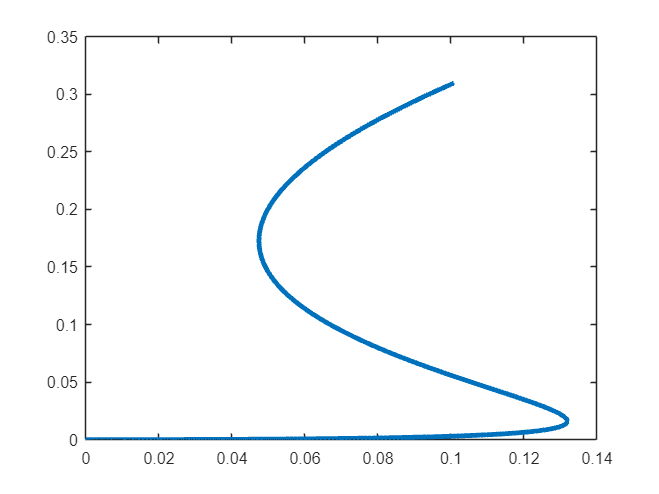


plot(x,y,'LineWidth',3)

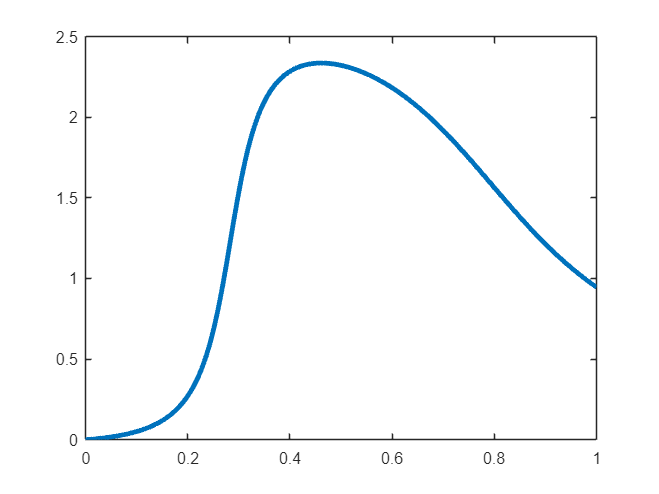

plot(s,theta,'LineWidth',3)

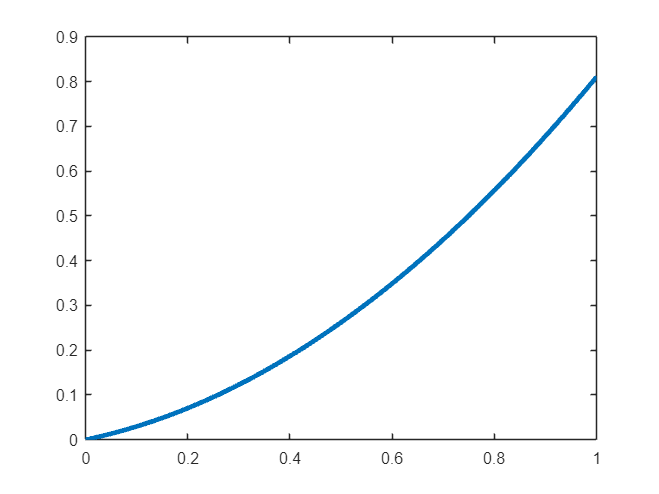

plot(s,y_dot,'LineWidth',3)

max(x_dot)

ans = 1

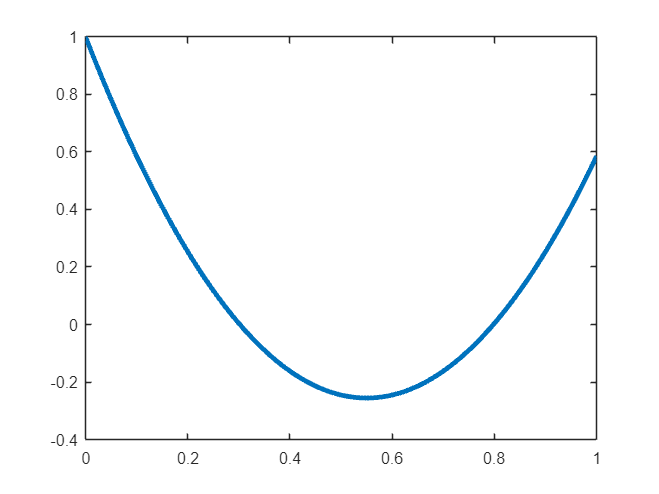

plot(s,x_dot,'LineWidth',3)


v = sqrt(x_dot.^2 + y_dot.^2) .* s_dot

v =          0    0.0018    0.0036    0.0054    0.0072    0.0090    0.0108    0.0126    0.0144    0.0162    0.0180    0.0197    0.0215    0.0233    0.0250    0.0268    0.0286    0.0303    0.0320    0.0338    0.0355    0.0372    0.0389    0.0406    0.0423    0.0439    0.0456    0.0472    0.0489    0.0505    0.0521    0.0537    0.0553    0.0569    0.0584    0.0600    0.0615    0.0630    0.0645    0.0660    0.0674    0.0689    0.0703    0.0717    0.0731    0.0745    0.0759    0.0772    0.0785    0.0798


w = (y_ddot.*x_dot - x_ddot.*y_dot)./(x_dot.^2 + y_dot.^2) .* s_dot

w =          0    0.0004    0.0009    0.0013    0.0017    0.0021    0.0026    0.0030    0.0035    0.0039    0.0043    0.0048    0.0052    0.0057    0.0061    0.0066    0.0071    0.0075    0.0080    0.0085    0.0090    0.0095    0.0100    0.0105    0.0110    0.0116    0.0121    0.0127    0.0132    0.0138    0.0144    0.0150    0.0156    0.0162    0.0168    0.0175    0.0181    0.0188    0.0195    0.0202    0.0209    0.0216    0.0224    0.0232    0.0240    0.0248    0.0256    0.0265    0.0273    0.0282


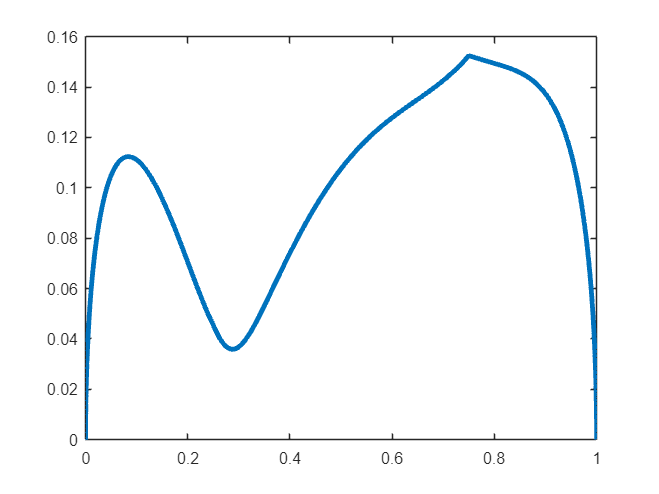

plot(s,v,'LineWidth',3)

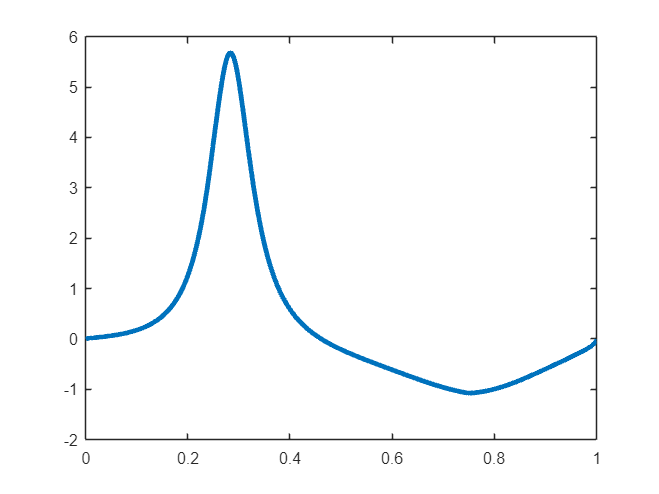

plot(s,w,'LineWidth',3)

max(v)

ans = 0.1525

max(w)

ans = 5.6801



b = 1

b = 1

y1 = x + b.*cos(theta)

y1 =     1.0000    1.0000    1.0000    1.0001    1.0001    1.0002    1.0003    1.0004    1.0006    1.0007    1.0009    1.0011    1.0013    1.0015    1.0018    1.0020    1.0023    1.0026    1.0029    1.0032    1.0036    1.0039    1.0043    1.0047    1.0051    1.0056    1.0060    1.0065    1.0070    1.0075    1.0080    1.0085    1.0091    1.0096    1.0102    1.0108    1.0114    1.0120    1.0127    1.0133    1.0140    1.0147    1.0154    1.0161    1.0168    1.0175    1.0183    1.0190    1.0198    1.0206


y2 = y + b.*sin(theta)

y2 =          0    0.0000    0.0000    0.0000    0.0000    0.0001    0.0001    0.0001    0.0001    0.0002    0.0002    0.0003    0.0003    0.0004    0.0004    0.0005    0.0006    0.0006    0.0007    0.0008    0.0009    0.0010    0.0011    0.0012    0.0013    0.0014    0.0015    0.0016    0.0018    0.0019    0.0021    0.0022    0.0024    0.0025    0.0027    0.0029    0.0030    0.0032    0.0034    0.0036    0.0038    0.0040    0.0043    0.0045    0.0047    0.0050    0.0052    0.0055    0.0058    0.0061


y1_dot = cos(theta).*v - b.*sin(theta).*w

y1_dot =          0    0.0018    0.0036    0.0054    0.0072    0.0090    0.0108    0.0126    0.0144    0.0162    0.0180    0.0197    0.0215    0.0233    0.0250    0.0268    0.0285    0.0303    0.0320    0.0338    0.0355    0.0372    0.0389    0.0406    0.0422    0.0439    0.0456    0.0472    0.0489    0.0505    0.0521    0.0537    0.0553    0.0568    0.0584    0.0599    0.0614    0.0629    0.0644    0.0659    0.0674    0.0688    0.0702    0.0716    0.0730    0.0744    0.0757    0.0770    0.0783    0.0796


y2_dot = sin(theta).*v + b.*cos(theta).*w

y2_dot =          0    0.0004    0.0009    0.0013    0.0017    0.0021    0.0026    0.0030    0.0035    0.0039    0.0043    0.0048    0.0052    0.0057    0.0062    0.0066    0.0071    0.0076    0.0080    0.0085    0.0090    0.0095    0.0100    0.0106    0.0111    0.0116    0.0122    0.0127    0.0133    0.0139    0.0145    0.0151    0.0157    0.0163    0.0170    0.0176    0.0183    0.0190    0.0197    0.0204    0.0212    0.0219    0.0227    0.0235    0.0243    0.0251    0.0260    0.0269    0.0278    0.0287
